IMPORTANT: ALL PRE-MODS.

# AT-AT(wo)

Memorial de cálculos para fins de documentação do projeto AT-AT (2023-1).

Agradecimentos eternos ao professor Victor Paiva pela ajuda. 

## Variáveis

### Constantes

% constantes
g = -9.80665; % [m/s^2]

### Componentes

Usando dados retirados do NX, foram montadas classes correspondentes a cada componente, com suas respectivas propriedades, além de uma classe para o material trabalhado - MDF - e o conjunto total do robô - AT-AT.

pata = paw;
argola = hoop;
tornozelo = ankle;
canela = shin;
joelho = knee;
coxa = thigh;
conector = connector;
barriga = underbelly;
casca = body;
pescoco = neck;
cabeca = head;
corpo = ATAT;

## Diagramas de Corpo Livre

### Pata

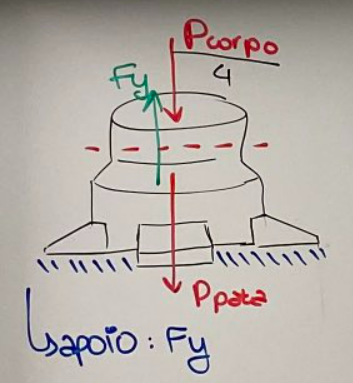

onde:

- Wf = peso do material da pata [N];

- Wb = peso do corpo acima desse componente [N];

- Ny = reação do chão [N];

- Ay = reação do tornozelo [N];

WbMAX = pata.Wb*(4/3); % Wb over 3 paws
Wf = g*(pata.mass);
Ny = -(g*body.mass)/4;

### Argola

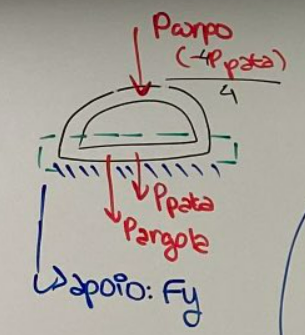

onde:

- Wb = peso do corpo acima desse componente [N];

- Wl = peso da coxa [N];

- Ay = reação do tornozelo [N]; 

hoop.Wb = pata.Wb - 4*Wf;


### Tornozelo

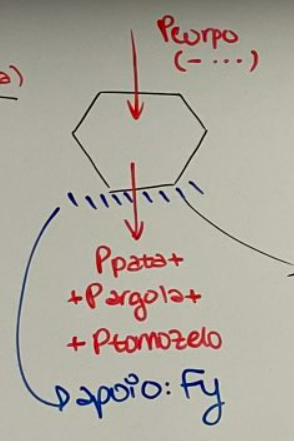

### Canela

Diagrama de corpo livre referente a apenas o componente individual de uma placa correspondente à canela.

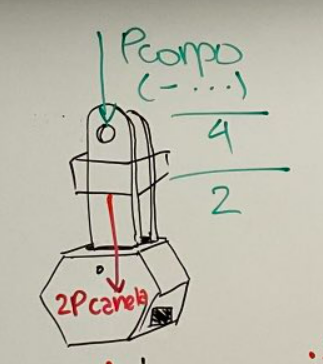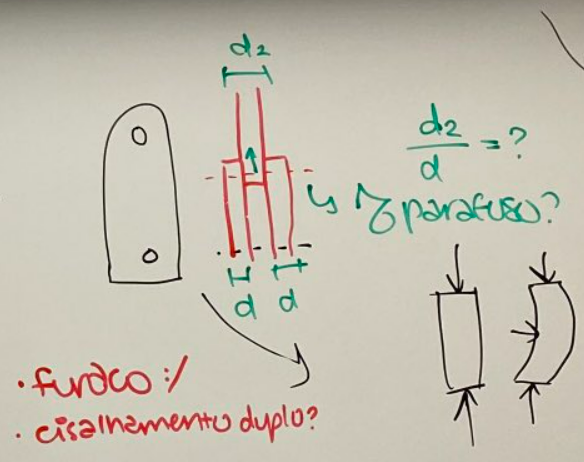

### Parafuso do joelho

### Coxa

### Conector da coxa

### Barriga

### Corpo

### Pescoço

### Cabeça

## Situação Particular: AT-AT estático

Considerando a condição inicial do AT-AT estático, primeiro foram calculadas forças considerando o equilíbrio estático do robô.

## Situação Geral: AT-AT em movimento

Considerando a condição mais genérica do AT-AT em movimento, em seguida foram calculadas forças visando uma construção capaz de se sustentar.

## Funções

function I=MoI(short,long) % momento de inércia 
    I=(short^3*long)/12;
end

function P=Pcol(E,I,L) % tensão crítica de flambagem
    P=(pi^2*E*I)/L^2;
end